# Løsning til 2017 eksamen

## Opgave 1

## Opgave 2

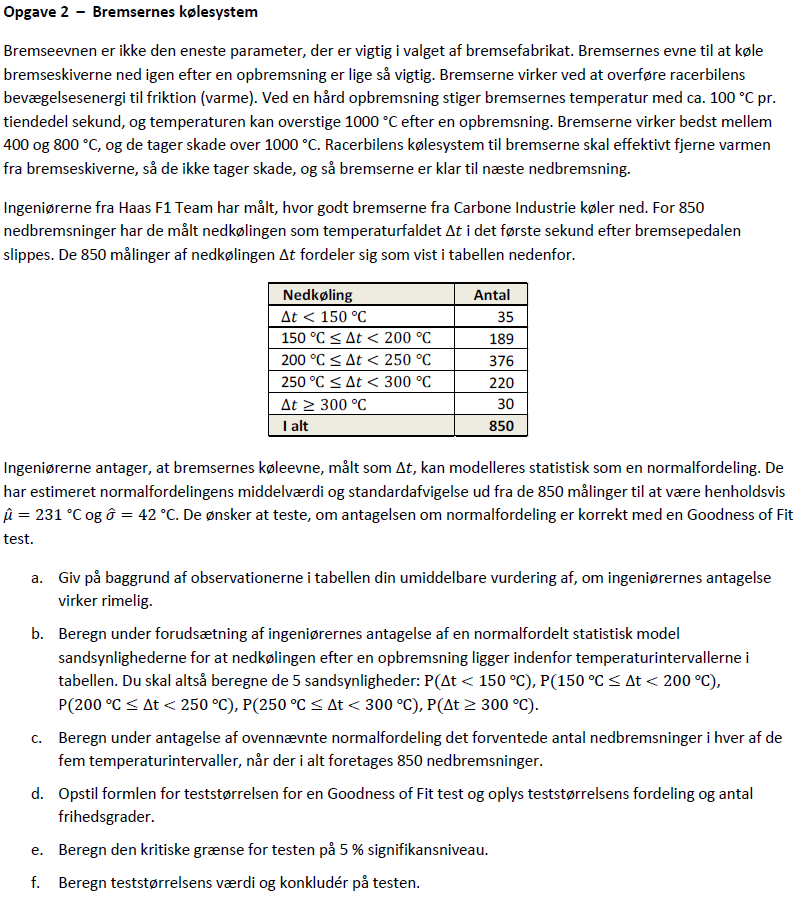

clc; clear;

% Opgave a

% Data fra opgaven
sigma = 42;
mu = 231;

% Antal observeringer i tabellen
obs = 1:1:5;
delta_ts = [35, 189, 376, 220, 30];

% Bar plot og dist plot
figure;
bar(obs, delta_ts);

X = categorical({'0-150','150-200','200-250','250-300', '300+'});
X2 = reordercats(X,{'0-150','150-200','200-250','250-300', '300+'});
Y = delta_ts;
bar(X,Y)

dist = makedist("Normal", "mu",mu, "sigma",sigma);

x = 0:1:400;
int = [-5, 2, 0, 2, 5]



pd = pdf(dist,x)

plot(x, pd, 'LineWidth',2), xlim([50, 400])


sort(delta_ts)

sigma = 42;
mu = 231;

inter = [150,200];
interny = [150,400];


IntervalNormal(mu, sigma, 0, 400, [150,200,250,300])
IntervalNormal(mu, sigma, 0, 400,interny)





% Opgave b

% Mindre end 150C
p1 = normcdf(150, mu, sigma)


plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 1:150), pd(1, 1:150))
hold off


% Mellem 150 og 200C
p2 = normcdf(200, mu, sigma) - p1

plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 150:201), pd(1, 150:201))
hold off

% Mellem 200 og 250C
p3 = normcdf(250, mu, sigma) - normcdf(200, mu, sigma)
plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 200:251), pd(1, 200:251))
hold off

% Mellem 250 og 300C
p4 = normcdf(300, mu, sigma) - normcdf(250, mu, sigma)

plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 250:301), pd(1, 250:301))
hold off


% Mere end 300C
p5 = 1 - normcdf(300, mu, sigma)

plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

aa = area(x(1, inter(end):end), pd(1, inter(end):end), facecolor="b", DisplayName="p5");
legend(Location="best")
hold off

plot(x, pd, 'LineWidth',2, DisplayName="Fordelingsfunktion"), xlim([50, 400]), grid()
hold on
a1 = area(x(1, 1:151), pd(1, 1:151), DisplayName="p1 = " + p1);
a2 = area(x(1, 150:201), pd(1, 150:201), DisplayName="p2 = " + p2);
a3 = area(x(1, 200:251), pd(1, 200:251), DisplayName="p3 = " + p3);
a4 = area(x(1, 250:301), pd(1, 250:301), DisplayName="p4 = " + p4);
a5 = area(x(1, 300:end), pd(1, 300:end), DisplayName="p5 = " + p5);
alpha([a1,a2,a3,a4,a5], 0.25)
legend(Location="northwest")
hold off

x(1, inter(end):end)


% Opgave c
ps = [p1, p2, p3, p4, p5];
n_obs = 850;

forv_obs = ps*n_obs


disp(table(delta_ts', ps', forv_obs', VariableNames=["Observerede værdier", "Sandsynligheder", "Forventede værdier"]))


% Opgave d
% k er antal observationer
% p er antal parametre - her er er der 2 - middelværdi og afvigelse
obs = delta_ts
forv = forv_obs

params = size([obs;forv])

chisqstat = chi2inv(0.95, 2)


chi2_0 = sum(((obs - forv) .^ 2) ./ forv)

df =  length(obs) - params(1) - 1

chisqstat = chi2inv(0.95, df)

xs = linspace(0, 20, 300);
pd = chi2pdf(xs, df);

tvalpdf = chi2pdf(chi2_0, df)

plot(xs, pd, "DisplayName","Students t-fordeling")
hold on

scatter(chi2_0, tvalpdf,"filled", "DisplayName","t-statistik")

title("Visualisering af t-fordelingen og kritisk(e) grænse(r)")
xline(chisqstat,'-', "DisplayName","Kritisk grænse")
legend('show', 'location','best')

hold off


chi2normal_Test_7_8(obs, forv, 95,2)

## Opgave 3

clc; clear;

data = xlsread("Data_M4STI1_2017E.xlsx", "K:L");

data'

ans =    92.5320   92.8750   94.4790   92.1390   93.7850   93.3090   92.7660   91.9430   92.7160   92.9130   91.5310   93.1920   92.1780   92.9060   93.3360   92.0950   92.7120   93.3500   91.1640   94.0360
   90.2740   95.8780   92.0530   94.2860   89.8920   94.6340   95.8220   95.3620   90.3720   93.9600   91.3250   92.0660   91.2900   89.9230   98.2730   92.3700   87.9030   94.8230   92.6470   95.0980



deskripts(data', ["Brembo","Cl"]);

    Datanavn    Middelværdi    Varians    Standardafvigelse    Målepunkter
    ________    ___________    _______    _________________    ___________

    "Brembo"      92.798       0.67258         0.82011             20     
    "Cl"          92.913        6.8375          2.6149             20     




alpha = 0.05;

finv(alpha/2,19,19)

ans = 0.3958

finv(1-alpha/2,19,19)

ans = 2.5265



[h,p,ci,stats]=vartest2(data(:,1), data(:,2),"Alpha",alpha,"Tail","both")

h = 1

p = 5.1338e-06

ci =     0.0389
    0.2485


stats = struct with fields:
    fstat: 0.0984
      df1: 19
      df2: 19




var(data(:,1))/var(data(:,2))

ans = 0.0984

Teststørrelsens værdi


$$F_{0}=\frac{{s_{1}}^{2}}{{s_{2}}^{2}}$$

-----------------------------------------------------------------
t-værdiens formel


$$F_{\alpha }=\frac{\mathrm{finv}\,\mathrm{df}}{20}$$

-----------------------------------------------------------------
    Signifikansniveau    Grænse    Teststatistik
    _________________    ______    _____________

          0.05           2.1683      0.098366   



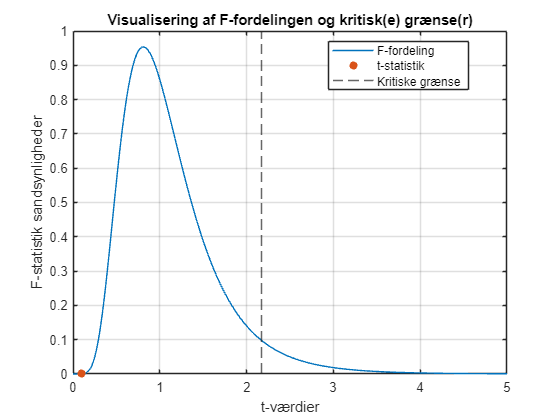

Da h = 0 forkastes nulhypotesen ikke
Ydermere ses det også at F-værdien 0.098366 ikke overstiger den kritiske grænse på 2.1683


ans = struct with fields:
    stats: [1×1 struct]
        p: 1.0000
       ci: [2×1 double]




VarTest2pop_Test6(data(:,1), data(:,2),"right", 95, 0)